# **Vision Artificial. GIEC.**

# **Sistemas de Vision Artificial. GIC.**

**Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

# Topic 6: exercise 02 - Perspective Correction using Homography

In order to correct the perspective of an object you will need to estimate the perspective transformation. Four pairs of corresponding points are enough to recover a perspective transformation between two images.

Correct the perspective of the card from the image "card.jpg", following the next steps:

**Questions**

- Load the image "card.jpg".

- Click on the four corners of the card to obtain the first four points using `impixel` function. Note: use the following order to obtain the four points: 1) Upper left corner, 2) Upper right corner, 3) Lower right corner, 4)Lower left corner.

- Calculate the four points of the poker card without perspective distortion, taking to into account that a poker card has a size of 67 mm by 100 mm approximately.

- Estimate the perspective transformation using `estimateGeometricTransform` function.

- Apply the perspective transformation using `imwarp` function.

Step 1) Load image.

clear all;
close all;

% Read original image.
I = imread('card.jpg');

Step 2) Click on the four corners.

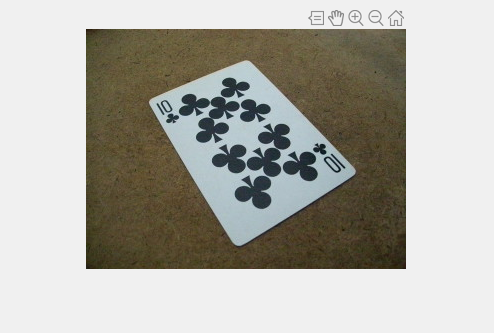

% NOTE: impixel 
% Use normal button clicks to select pixels. 
% Press Backspace or Delete to remove the previously selected pixel. 
% To add a final pixel and finish pixel selection in one step, press shift-click, or right-click or double-click. 
% To finish selecting pixels without adding a final pixel, press Return.
[x, y , P] = impixel(I);

srcPoints = [x y];

Step 3) Projected four points

scale = 2;
card_w = 67*scale;
card_h = 100*scale;
dstPoints = [x(1) y(1);x(1)+card_w y(1); x(1) y(1)+card_h;x(1)+card_w y(1)+card_h];

Step 4) Estimate the perspective transformation (Homography)    

tform = estimateGeometricTransform(srcPoints,dstPoints,'Projective');

Step 5) Apply the perspective transformation

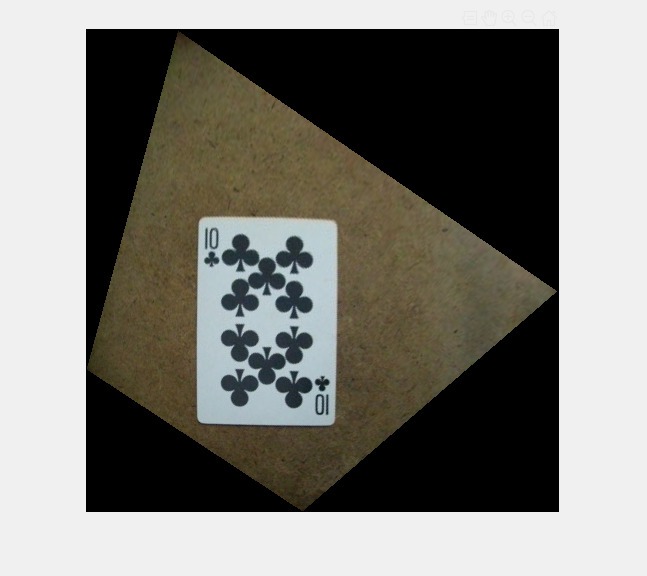

I2=imwarp(I,tform);
imshow(I2);